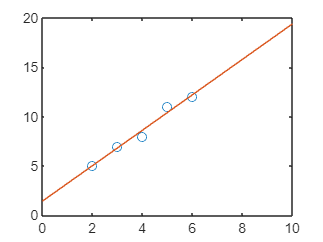

v1 = [2,3,4,5,6];
v2 = [5,7,8,11,12];

A = cat(2,ones(1, 5)', v1');
xls = LSsolver(A, v2');

plot(v1, v2, "-o", LineStyle="none");
hold on;
x = linspace(0,10,5);
plot(x, xls(1) + xls(2)*x);

function [xls] = LSsolver(A, b)
    xls = inv(A'*A) * (A'*b);
end